# Discrete Cosine Transform

The formula for the DCT of a matrix is given by:


$$B_{pq} = \alpha_p \alpha_q \sum_{m=0}^{M-1} \sum_{n=0}^{N-1} {A_{mn} \cos\frac{\pi (2m+1)p}{2M} \cos\frac{\pi (2n+1)q}{2N} , \matrix{0 \leq p \leq M-1 \cr 0 \leq q \leq N -1}$$


where $\alpha_p = \begin{cases} 1/\sqrt{M}, & p=0 \\ \sqrt{2/M} , & 1 \leq p \leq M-1 \end{cases}$ and $\alpha_q = \begin{cases} 1/\sqrt{N}, & q=0 \\ \sqrt{2/N} , & 1 \leq q \leq N-1 \end{cases}$

It is an invertible transform, and its inverse is given by:


$$A_{mn} = \sum_{m=0}^{M-1} \sum_{n=0}^{N-1} {\alpha_p \alpha_q B_{pq} \cos\frac{\pi (2m+1)p}{2M} \cos\frac{\pi (2n+1)q}{2N} , \matrix{0 \leq m \leq M-1 \cr 0 \leq n \leq N -1}$$


where $\alpha_p$ and $\alpha_q$ are as described previously.

From the inverse transform equation, we can observe that any $M \times N$ image matrix $A_{mn}$ can be written as a sum $MN$ functions of the form:


$$\alpha_p \alpha_q \cos\frac{\pi (2m+1)p}{2M} \cos\frac{\pi (2n+1)q}{2N},  \matrix{0 \leq m \leq M-1 \cr 0 \leq n \leq N -1}$$


These are the basis functions of the DCT, and the coefficients $B_{pq}$ can be regarded as the weights applied to each basis function. For 8x8 matrices, the 64 basis functions are illustrated by the following image:

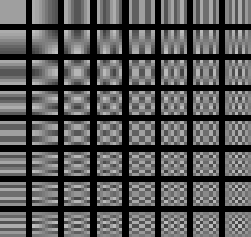 

Horizontal frequencies increase from left to right, and vertical frequencies increase from top to bottom.The constant-valued function at the top left is called the DC (Direct Current) basis function, while the rest are known as AC (Alternating Current) bases.

We can see what the basis functions would look like for different dimensions below:

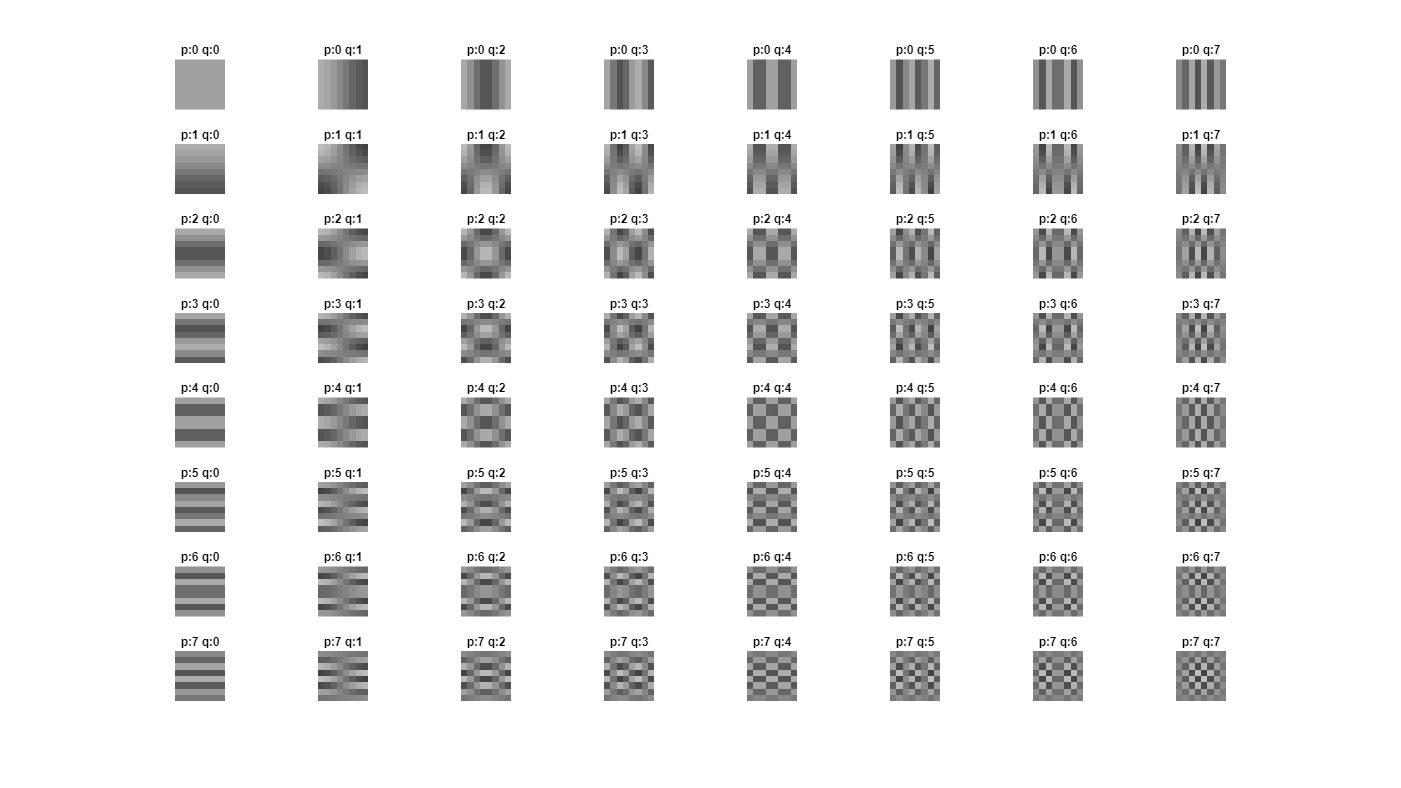

 

basis_size = 8;

M = basis_size; N = basis_size;
alpha = @(x, Y) (x==0)*(1/sqrt(Y)) + (x~=0)*(sqrt(2/Y)); % to calculate alpha_p and alpha_q
basis_func = @(p, q, m, n) alpha(p, M) * alpha(q, N) * cos(pi * (2*m+1) * p / (2*M)) * cos(pi * (2*n+1) * q / (2*N));

h = figure;
tiledlayout(M, N, 'TileSpacing','tight');
for p = 0 : M-1
    for q = 0 : N-1
        cimg = zeros(M, N, "double");
        for m = 0 : M-1
            for n = 0 : N-1
                cimg(m+1, n+1) = 0.5 + basis_func(p, q, m, n);
            end
        end
        nexttile;
        imshow(cimg, 'InitialMagnification', 'fit');
        %imshow(imresize(cimg, [64 64], 'nearest'));
        title(sprintf("p:%d q:%d", p, q), "Color", 'k');
    end
end
set(h,'Units','normalized','Position',[0 0 1 1]); 

clf(figure);

## Applying DCT on an Image

We can now apply the DCT on an image of our choice using the **dct2** library function or manually, as shown below:

### Load the Image from Disk

img_path = ("D:\backups\Backup 22-04-23\Pictures\Cowboy Bebop - Session 17 - Mushroom Hunting.mkv_snapshot_19.01.624.jpg");
img = imread(img_path);
fprintf("image read from disk:");

image read from disk:

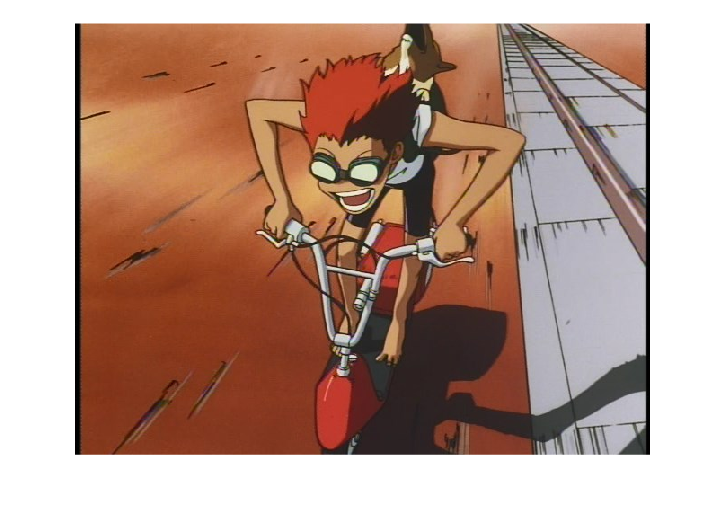

imshow(img);

img_init_filesize = dir(img_path).bytes;
fprintf('initial filesize of image: %d bytes', img_init_filesize);

initial filesize of image: 59598 bytes

### Set Dimension of DCT

dim = (16);

The image dimensions must be perfect multiples of the dimension chosen above, hence, we will pad the image if needed.

imsize = size(img);
pad_dim = [(mod(imsize(1), dim) ~= 0)*(dim - mod(imsize(1), dim)), (mod(imsize(2), dim) ~= 0)*(dim - mod(imsize(2), dim))];
pad_img = padarray(img, pad_dim, 0, "post");
pimsize = size(pad_img);
fprintf("original image dimensions: %d x %d", imsize(1), imsize(2));

original image dimensions: 480 x 640

fprintf("padded image dimensions:   %d x %d", pimsize(1), pimsize(2));

padded image dimensions:   480 x 640

fprintf("number of blocks to perform DCT on: %d", pimsize(1) * pimsize(2) / (dim * dim));

number of blocks to perform DCT on: 1200

Once padded, we can now calculate the DCT of the image:

 

dct = @(b_struct) block_apply_dct(b_struct.data, dim);

dct_mat_r = blockproc((im2double(pad_img(:,:,1)) .* 2 - 1), [dim dim], dct);
dct_mat_g = blockproc((im2double(pad_img(:,:,2)) .* 2 - 1), [dim dim], dct);
dct_mat_b = blockproc((im2double(pad_img(:,:,3)) .* 2 - 1), [dim dim], dct);

We can observe that for each 8x8 block of the image, most of the information is always near the top left corner, which corresponds to the lower frequency cosines:

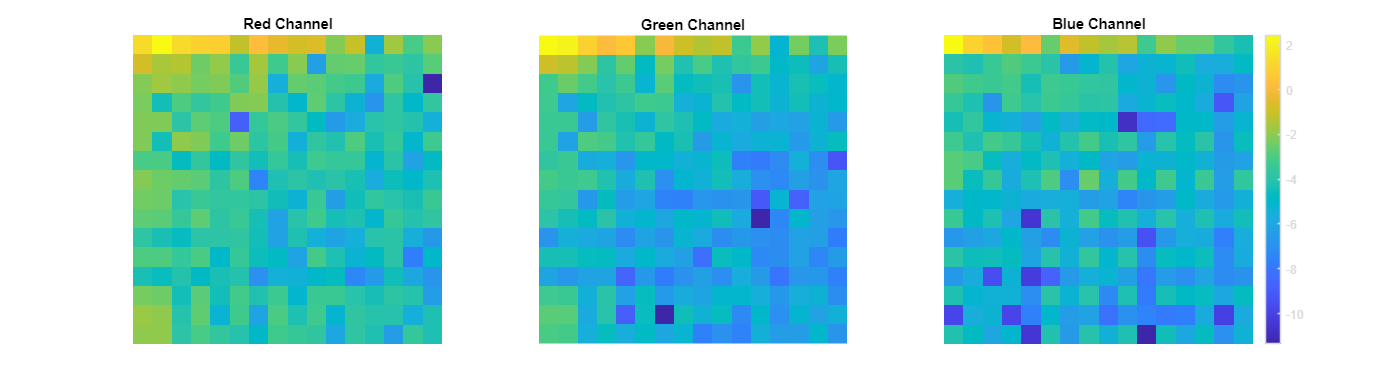

h = figure;
tiledlayout(1, 3);
nexttile;
imshow(imresize(log(abs(dct_mat_r(1:dim,1:dim))), [256 256], "nearest"), []);
title("Red Channel", "Color", 'k');
nexttile;
imshow(imresize(log(abs(dct_mat_g(1:dim,1:dim))), [256 256], "nearest"), []);
title("Green Channel", "Color", 'k');
nexttile;
imshow(imresize(log(abs(dct_mat_b(dim+1:2*dim,1:dim))), [256 256], "nearest"), []);
title("Blue Channel", "Color", 'k');
colormap parula
colorbar
set(h,'Units','normalized','Position',[0 0 1 .5]);

clf(h);

The higher fequency cosines represent the areas of the image where there are sharp changes in frequency, which corresponds to fine detail. This proves the principle of DCT-based compression, that by discarding the higher frequency cosine coefficients, we can effectively compress images without compromising much on quality, since most images do not contain large amounts of detail.

## Applying the Compression

There are quite a few ways of dropping cosine coefficients. We can use a mask to the preserve values of the top left coefficients and make the rest as zero; JPEG compression which uses a quantization table to scale down the coefficients; or applying a threshold on the minimum absolute value of the coefficients. We will test out all three of the above and compare the resulting images.

To get the compressed images back from the DCT coefficients, we will use inverse DCT, described in the next section.

### Method 1: Masking

We can choose a fixed number of coefficients from the top left to keep and drop the rest to zero.

num_ones = (8);

mask_mat = zeros(dim, dim);
for i = 1 : num_ones
    for j = 1 : num_ones
        if (i+j <= (num_ones+1))
            mask_mat(i,j) = 1;
        end
    end
end
fprintf("mask matrix:");

mask matrix:

disp(mask_mat);

     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0

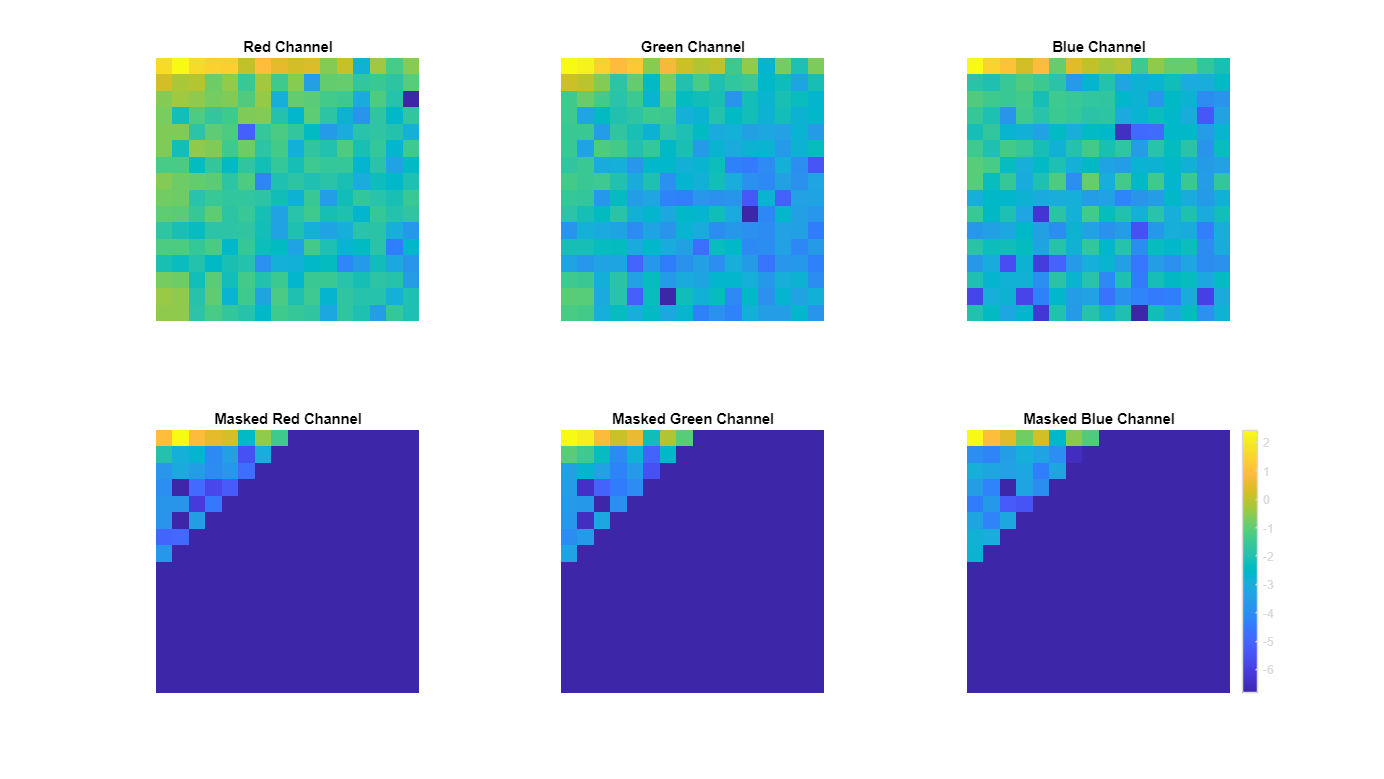


mask = @(b_struct) b_struct.data .* mask_mat;

mask_dct_r = blockproc(dct_mat_r, [dim dim], mask);
mask_dct_g = blockproc(dct_mat_g, [dim dim], mask);
mask_dct_b = blockproc(dct_mat_b, [dim dim], mask);

h = figure;
tiledlayout(2, 3);
nexttile;
imshow(imresize(log(abs(dct_mat_r(1:dim,1:dim))), [256 256], "nearest"), []);
title("Red Channel", "Color", 'k');
nexttile;
imshow(imresize(log(abs(dct_mat_g(1:dim,1:dim))), [256 256], "nearest"), []);
title("Green Channel", "Color", 'k');
nexttile;
imshow(imresize(log(abs(dct_mat_b(dim+1:2*dim,1:dim))), [256 256], "nearest"), []);
title("Blue Channel", "Color", 'k');
nexttile;
imshow(imresize(log(abs(mask_dct_r(1:dim,1:dim))), [256 256], "nearest"), []);
title("Masked Red Channel", "Color", 'k');
nexttile;
imshow(imresize(log(abs(mask_dct_g(1:dim,1:dim))), [256 256], "nearest"), []);
title("Masked Green Channel", "Color", 'k');
nexttile;
imshow(imresize(log(abs(mask_dct_b(dim+1:2*dim,1:dim))), [256 256], "nearest"), []);
title("Masked Blue Channel", "Color", 'k');
colormap parula
colorbar
set(h,'Units','normalized','Position',[0 0 1 1]);

clf(h);

Here, the lower right triangle values have all become zero, and the rest have been left unchanged, as seen below:

fprintf("original matrix block:");

original matrix block:

disp(dct_mat_r(1:num_ones+1, 1:num_ones+1));

   -2.5990   -9.4654   -2.4462    1.6752    1.4163    0.1328   -0.7325   -0.3335    0.2059
    0.1978   -0.0855   -0.1049    0.0304    0.0549    0.0090   -0.0764   -0.0115    0.0470
   -0.0428    0.0726   -0.0531   -0.0333    0.0418    0.0167   -0.0617    0.0007    0.0243
    0.0353    0.0029   -0.0158   -0.0073    0.0113    0.0418   -0.0428    0.0042   -0.0013
   -0.0411    0.0409    0.0052   -0.0210   -0.0155   -0.0000   -0.0080    0.0145   -0.0071
    0.0403   -0.0028   -0.0528   -0.0416    0.0115    0.0294   -0.0057   -0.0129    0.0008
   -0.0139    0.0148    0.0020   -0.0073    0.0020    0.0066   -0.0028    0.0079    0.0030
    0.0441   -0.0298   -0.0239   -0.0207    0.0057    0.0154    0.0001    0.0036   -0.0055
   -0.0314    0.0304   -0.0048   -0.0089   -0.0070    0.0068   -0.0054   -0.0026   -0.0010



fprintf("masked matrix block:");

masked matrix block:

disp(mask_dct_r(1:num_ones+1, 1:num_ones+1));

   -2.5990   -9.4654   -2.4462    1.6752    1.4163    0.1328   -0.7325   -0.3335         0
    0.1978   -0.0855   -0.1049    0.0304    0.0549    0.0090   -0.0764         0         0
   -0.0428    0.0726   -0.0531   -0.0333    0.0418    0.0167         0         0         0
    0.0353    0.0029   -0.0158   -0.0073    0.0113         0         0         0         0
   -0.0411    0.0409    0.0052   -0.0210         0         0         0         0         0
    0.0403   -0.0028   -0.0528         0         0         0         0         0         0
   -0.0139    0.0148         0         0         0         0         0         0         0
    0.0441         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0



### Method 2: JPEG Quantization

Shown below is the standardized JPEG quantization table for a compression level of approximately 50%:


$$\left\lbrack \begin{array}{cccccccc}
16 & 11 & 10 & 16 & 24 & 40 & 51 & 61\\
12 & 12 & 14 & 19 & 26 & 58 & 60 & 55\\
14 & 13 & 16 & 24 & 40 & 57 & 69 & 56\\
14 & 17 & 22 & 29 & 51 & 87 & 80 & 62\\
18 & 22 & 37 & 56 & 68 & 109 & 103 & 77\\
24 & 35 & 55 & 64 & 81 & 104 & 113 & 92\\
49 & 64 & 78 & 87 & 103 & 121 & 120 & 101\\
72 & 92 & 95 & 98 & 112 & 100 & 103 & 99
\end{array}\right\rbrack$$


Since the standard dimension is 8x8, we will use bicubic interpolation to resize it for our purposes.

quant_mat = [16 11 10 16 24 40 51 61;
             12 12 14 19 26 58 60 55;
             14 13 16 24 40 57 69 56;
             14 17 22 29 51 87 80 62;
             18 22 37 56 68 109 103 77;
             24 35 55 64 81 104 113 92;
             49 64 78 87 103 121 120 101;
             72 92 95 98 112 100 103 99];
res_quant_mat = imresize(quant_mat, [dim dim], "bicubic");
fprintf("resized quantization matrix:");

resized quantization matrix:

disp(res_quant_mat);

   16.8877   15.2942   12.1072   10.1187    9.3286   10.5830   13.8818   17.4514   21.2917   27.0493   34.7241   41.4705   47.2883   53.3059   59.5232   62.6318
   15.5120   14.3458   12.0134   10.6829   10.3542   11.7219   14.7859   17.9763   21.2932   28.3836   39.2475   46.7060   50.7591   54.6960   58.5168   60.4272
   12.7605   12.4489   11.8257   11.8113   12.4055   13.9998   16.5940   19.0261   21.2961   31.0522   48.2943   57.1771   57.7006   57.4763   56.5042   56.0181
   12.1199   12.0806   12.0021   12.5340   13.6762   15.6412   18.4291   21.5563   25.0230   35.2615   52.2719   61.4009   62.6486   60.9373   56.2668   53.9316
   13.5901   13.2409   12.5425   12.8510   14.1663   16.6464   20.2911   25.5670   32.4738   41.0117   51.1805   59.3776   65.6031   65.0789   57.8049   54.1680
   14.0732   13.9138   13.5948   14.2233   15.7994   18.3813   21.9692   28.4899   37.9434   47.8843   58.3125   66.0210   71.0098   69.0252   60.0673   55.5884
   13.5693   14.0992   15.1589   1

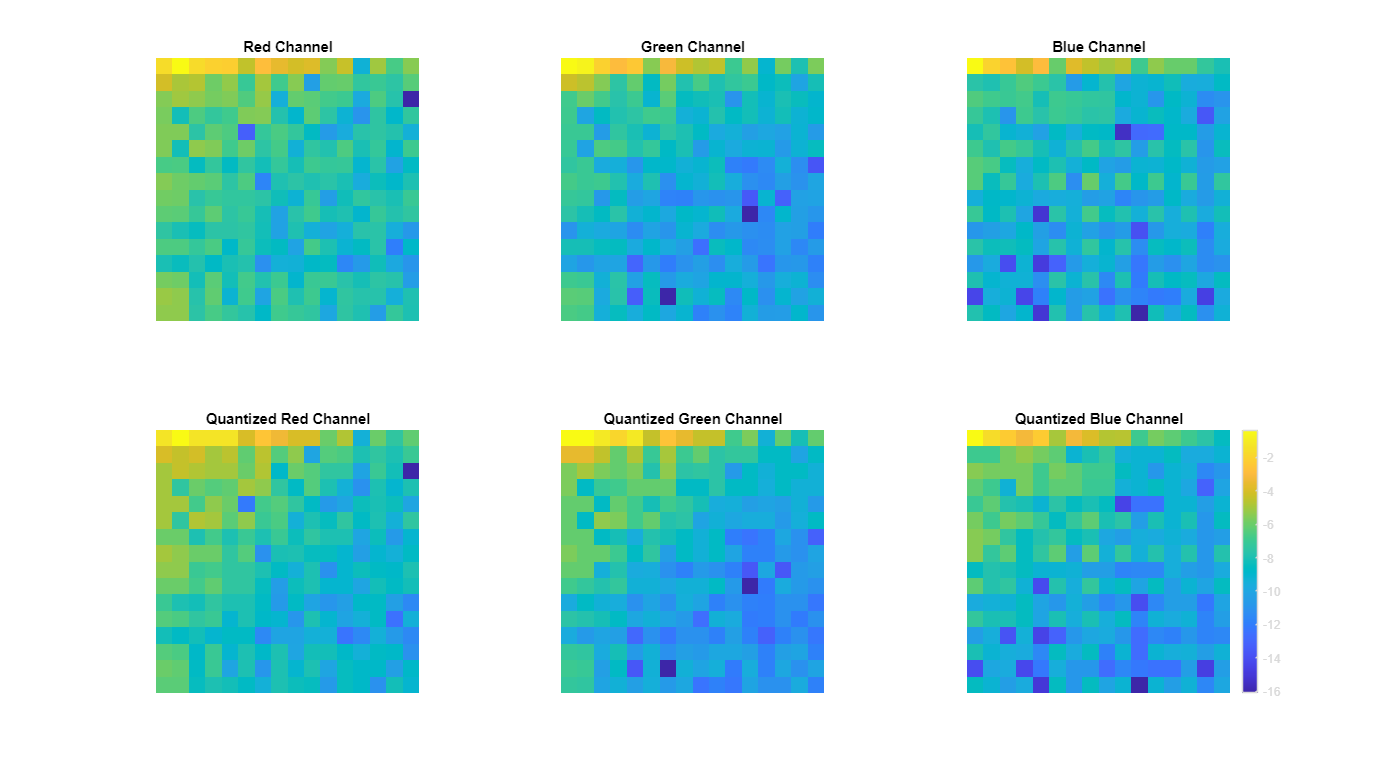


quantize = @(b_struct) sign(b_struct.data) .* round(abs(b_struct.data) ./ res_quant_mat, 1, "significant");
% quantize = @(b_struct) b_struct.data ./ res_quant_mat;

quant_dct_r = blockproc(dct_mat_r, [dim dim], quantize);
quant_dct_g = blockproc(dct_mat_g, [dim dim], quantize);
quant_dct_b = blockproc(dct_mat_b, [dim dim], quantize);

h = figure;
tiledlayout(2, 3);
nexttile;
imshow(imresize(log(abs(dct_mat_r(1:dim,1:dim))), [256 256], "nearest"), []);
title("Red Channel", "Color", 'k');
nexttile;
imshow(imresize(log(abs(dct_mat_g(1:dim,1:dim))), [256 256], "nearest"), []);
title("Green Channel", "Color", 'k');
nexttile;
imshow(imresize(log(abs(dct_mat_b(dim+1:2*dim,1:dim))), [256 256], "nearest"), []);
title("Blue Channel", "Color", 'k');
nexttile;
imshow(imresize(log(abs(quant_dct_r(1:dim,1:dim))), [256 256], "nearest"), []);
title("Quantized Red Channel", "Color", 'k');
nexttile;
imshow(imresize(log(abs(quant_dct_g(1:dim,1:dim))), [256 256], "nearest"), []);
title("Quantized Green Channel", "Color", 'k');
nexttile;
imshow(imresize(log(abs(quant_dct_b(dim+1:2*dim,1:dim))), [256 256], "nearest"), []);
title("Quantized Blue Channel", "Color", 'k');
colormap parula
colorbar
set(h,'Units','normalized','Position',[0 0 1 1]);

clf(h);

It can be seen that although the overall distribution of energy doesn't appear to have changed much, the actual enerygy values of the cells have been changed according to their importance:

fprintf("original matrix block:");

original matrix block:

disp(dct_mat_r(1:dim, 1:dim));

   -2.5990   -9.4654   -2.4462    1.6752    1.4163    0.1328   -0.7325   -0.3335    0.2059    0.2645   -0.0429   -0.1528   -0.0009    0.0747    0.0135   -0.0474
    0.1978   -0.0855   -0.1049    0.0304    0.0549    0.0090   -0.0764   -0.0115    0.0470    0.0003   -0.0250   -0.0255    0.0071    0.0097    0.0056   -0.0189
   -0.0428    0.0726   -0.0531   -0.0333    0.0418    0.0167   -0.0617    0.0007    0.0243    0.0200   -0.0120   -0.0099   -0.0005    0.0152    0.0045    0.0000
    0.0353    0.0029   -0.0158   -0.0073    0.0113    0.0418   -0.0428    0.0042   -0.0013    0.0211    0.0057    0.0010    0.0002    0.0059    0.0014    0.0067
   -0.0411    0.0409    0.0052   -0.0210   -0.0155   -0.0000   -0.0080    0.0145   -0.0071   -0.0019    0.0002   -0.0006    0.0046   -0.0061   -0.0042   -0.0008
    0.0403   -0.0028   -0.0528   -0.0416    0.0115    0.0294   -0.0057   -0.0129    0.0008    0.0066   -0.0038   -0.0156    0.0033    0.0080   -0.0012   -0.0109
   -0.0139    0.0148    0.0020   -

fprintf("quantized matrix block:");

quantized matrix block:

disp(quant_dct_r(1:dim, 1:dim));

   -0.2000   -0.6000   -0.2000    0.2000    0.2000    0.0100   -0.0500   -0.0200    0.0100    0.0100   -0.0010   -0.0040   -0.0000    0.0010    0.0002   -0.0008
    0.0100   -0.0060   -0.0090    0.0030    0.0050    0.0008   -0.0050   -0.0006    0.0020    0.0000   -0.0006   -0.0005    0.0001    0.0002    0.0001   -0.0003
   -0.0030    0.0060   -0.0040   -0.0030    0.0030    0.0010   -0.0040    0.0000    0.0010    0.0006   -0.0002   -0.0002   -0.0000    0.0003    0.0001    0.0000
    0.0030    0.0002   -0.0010   -0.0006    0.0008    0.0030   -0.0020    0.0002   -0.0001    0.0006    0.0001    0.0000    0.0000    0.0001    0.0000    0.0001
   -0.0030    0.0030    0.0004   -0.0020   -0.0010   -0.0000   -0.0004    0.0006   -0.0002   -0.0001    0.0000   -0.0000    0.0001   -0.0001   -0.0001   -0.0000
    0.0030   -0.0002   -0.0040   -0.0030    0.0007    0.0020   -0.0003   -0.0005    0.0000    0.0001   -0.0001   -0.0002    0.0001    0.0001   -0.0000   -0.0002
   -0.0010    0.0010    0.0001   -

### Method 3: Thresholding

We can set a threshold on the absolute value of the coefficients to efficiently nullify unimportant terms.

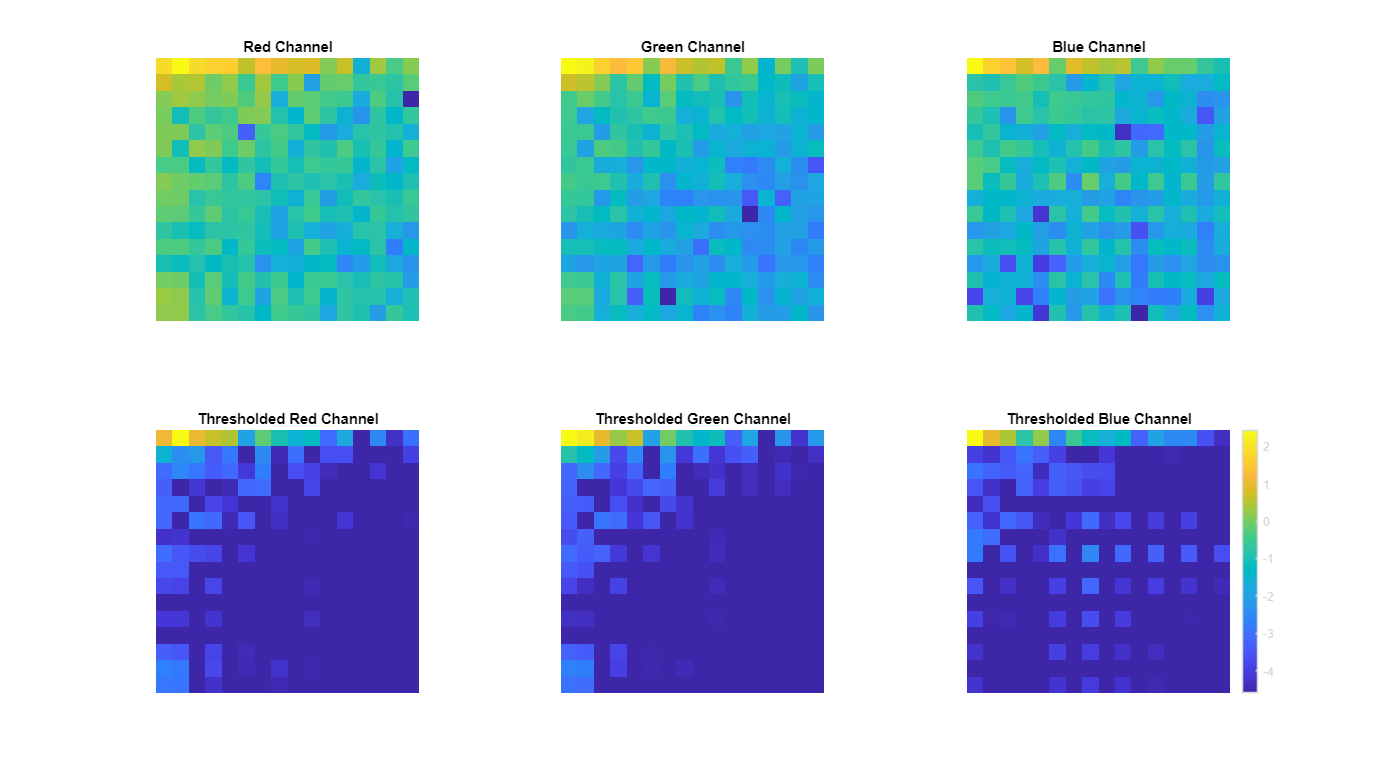

thresh_val = (0.01);

thresh_dct_r = dct_mat_r;
thresh_dct_r(abs(dct_mat_r) < thresh_val) = 0;
thresh_dct_g = dct_mat_g;
thresh_dct_g(abs(dct_mat_g) < thresh_val) = 0;
thresh_dct_b = dct_mat_b;
thresh_dct_b(abs(dct_mat_b) < thresh_val) = 0;

h = figure;
tiledlayout(2, 3);
nexttile;
imshow(imresize(log(abs(dct_mat_r(1:dim,1:dim))), [256 256], "nearest"), []);
title("Red Channel", "Color", 'k');
nexttile;
imshow(imresize(log(abs(dct_mat_g(1:dim,1:dim))), [256 256], "nearest"), []);
title("Green Channel", "Color", 'k');
nexttile;
imshow(imresize(log(abs(dct_mat_b(dim+1:2*dim,1:dim))), [256 256], "nearest"), []);
title("Blue Channel", "Color", 'k');
nexttile;
imshow(imresize(log(abs(thresh_dct_r(1:dim,1:dim))), [256 256], "nearest"), []);
title("Thresholded Red Channel", "Color", 'k');
nexttile;
imshow(imresize(log(abs(thresh_dct_g(1:dim,1:dim))), [256 256], "nearest"), []);
title("Thresholded Green Channel", "Color", 'k');
nexttile;
imshow(imresize(log(abs(thresh_dct_b(dim+1:2*dim,1:dim))), [256 256], "nearest"), []);
title("Thresholded Blue Channel", "Color", 'k');
colormap parula
colorbar
set(h,'Units','normalized','Position',[0 0 1 1]);

clf(h);

Applying the threshold drops the coefficients that are under the threshold value and replaces them with zero.

fprintf("original matrix block:");

original matrix block:

disp(dct_mat_r(1:dim, 1:dim));

   -2.5990   -9.4654   -2.4462    1.6752    1.4163    0.1328   -0.7325   -0.3335    0.2059    0.2645   -0.0429   -0.1528   -0.0009    0.0747    0.0135   -0.0474
    0.1978   -0.0855   -0.1049    0.0304    0.0549    0.0090   -0.0764   -0.0115    0.0470    0.0003   -0.0250   -0.0255    0.0071    0.0097    0.0056   -0.0189
   -0.0428    0.0726   -0.0531   -0.0333    0.0418    0.0167   -0.0617    0.0007    0.0243    0.0200   -0.0120   -0.0099   -0.0005    0.0152    0.0045    0.0000
    0.0353    0.0029   -0.0158   -0.0073    0.0113    0.0418   -0.0428    0.0042   -0.0013    0.0211    0.0057    0.0010    0.0002    0.0059    0.0014    0.0067
   -0.0411    0.0409    0.0052   -0.0210   -0.0155   -0.0000   -0.0080    0.0145   -0.0071   -0.0019    0.0002   -0.0006    0.0046   -0.0061   -0.0042   -0.0008
    0.0403   -0.0028   -0.0528   -0.0416    0.0115    0.0294   -0.0057   -0.0129    0.0008    0.0066   -0.0038   -0.0156    0.0033    0.0080   -0.0012   -0.0109
   -0.0139    0.0148    0.0020   -

fprintf("thresholded matrix block:");

thresholded matrix block:

disp(thresh_dct_r(1:dim, 1:dim));

   -2.5990   -9.4654   -2.4462    1.6752    1.4163    0.1328   -0.7325   -0.3335    0.2059    0.2645   -0.0429   -0.1528         0    0.0747    0.0135   -0.0474
    0.1978   -0.0855   -0.1049    0.0304    0.0549         0   -0.0764   -0.0115    0.0470         0   -0.0250   -0.0255         0         0         0   -0.0189
   -0.0428    0.0726   -0.0531   -0.0333    0.0418    0.0167   -0.0617         0    0.0243    0.0200   -0.0120         0         0    0.0152         0         0
    0.0353         0   -0.0158         0    0.0113    0.0418   -0.0428         0         0    0.0211         0         0         0         0         0         0
   -0.0411    0.0409         0   -0.0210   -0.0155         0         0    0.0145         0         0         0         0         0         0         0         0
    0.0403         0   -0.0528   -0.0416    0.0115    0.0294         0   -0.0129         0         0         0   -0.0156         0         0         0   -0.0109
   -0.0139    0.0148         0    

## Appying Inverse DCT

Now we will apply inverse DCT on each of the obtained matrices and compare the results based on different metrics.

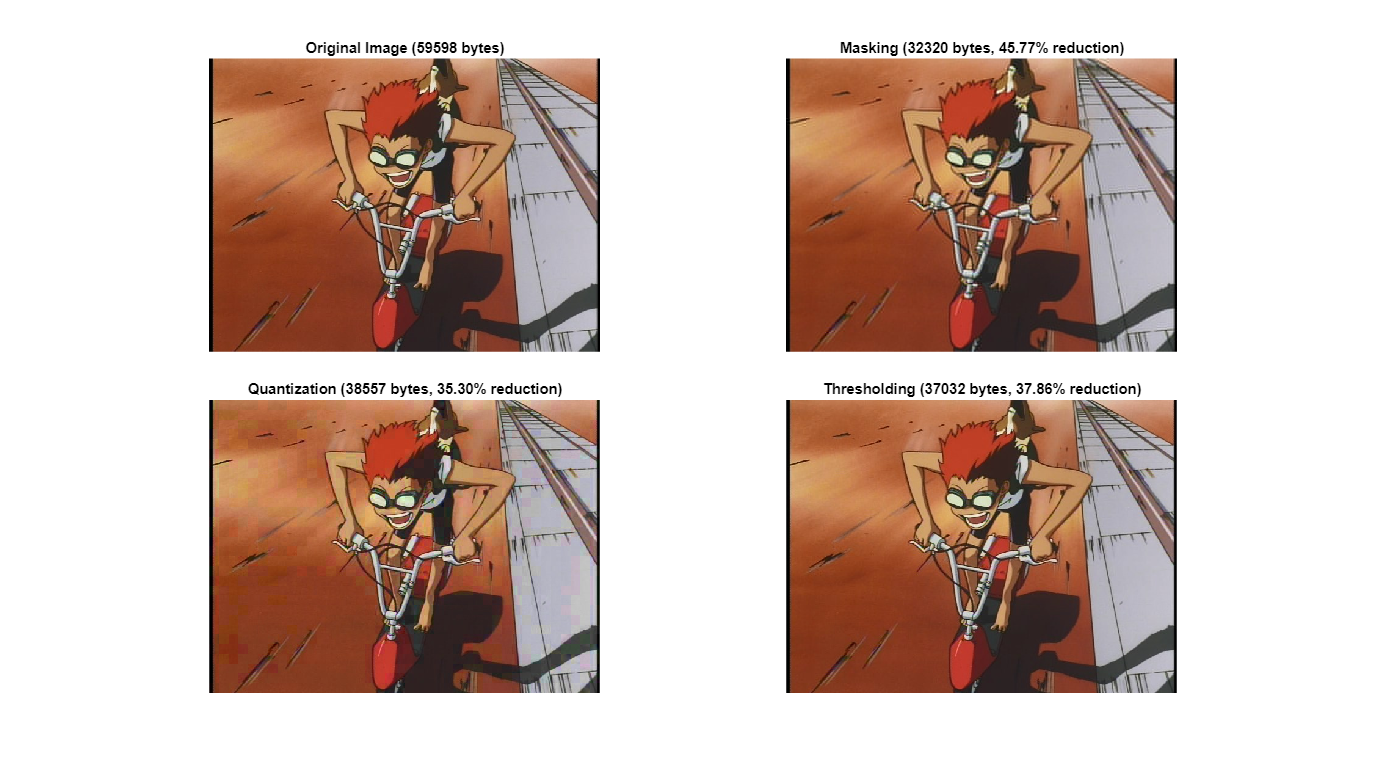

 

invdct = @(b_struct) block_apply_invdct(b_struct.data, dim);
qinvdct = @(b_struct) block_apply_invdct(b_struct.data .* res_quant_mat, dim);
must_crop = (imsize(1) ~= pimsize(1)) || (imsize(2) ~= pimsize(2));

mask_invdct_r = (blockproc(mask_dct_r, [dim dim], invdct) + 1) ./ 2;
mask_invdct_g = (blockproc(mask_dct_g, [dim dim], invdct) + 1) ./ 2;
mask_invdct_b = (blockproc(mask_dct_b, [dim dim], invdct) + 1) ./ 2;

mask_result = cat(3, mask_invdct_r, mask_invdct_g, mask_invdct_b);
if must_crop 
    mask_result = imcrop(mask_result, [0 0 imsize(2) imsize(1)]);
end
imwrite(mask_result, 'temp_mask.jpg');
mask_filesize = dir('temp_mask.jpg').bytes;

quant_invdct_r = (blockproc(quant_dct_r, [dim dim], qinvdct) + 1) ./ 2;
quant_invdct_g = (blockproc(quant_dct_g, [dim dim], qinvdct) + 1) ./ 2;
quant_invdct_b = (blockproc(quant_dct_b, [dim dim], qinvdct) + 1) ./ 2;

quant_result = cat(3, quant_invdct_r, quant_invdct_g, quant_invdct_b);
if must_crop
    quant_result = imcrop(quant_result, [0 0 imsize(2) imsize(1)]);
end
imwrite(quant_result, 'temp_quant.jpg');
quant_filesize = dir('temp_quant.jpg').bytes;

thresh_invdct_r = (blockproc(thresh_dct_r, [dim dim], invdct) + 1) ./ 2;
thresh_invdct_g = (blockproc(thresh_dct_g, [dim dim], invdct) + 1) ./ 2;
thresh_invdct_b = (blockproc(thresh_dct_b, [dim dim], invdct) + 1) ./ 2;

thresh_result = cat(3, thresh_invdct_r, thresh_invdct_g, thresh_invdct_b);
if must_crop
    thresh_result = imcrop(thresh_result, [0 0 imsize(2) imsize(1)]);
end
imwrite(thresh_result, 'temp_thresh.jpg');
thresh_filesize = dir('temp_thresh.jpg').bytes;

h = figure;
tiledlayout(2, 2, 'TileSpacing','tight');
nexttile;
imshow(img);
title(sprintf("Original Image (%d bytes)", img_init_filesize), "Color", 'k');
nexttile;
imshow(mask_result);
title(sprintf("Masking (%d bytes, %.2f%% reduction)", mask_filesize, ((img_init_filesize - mask_filesize) / img_init_filesize * 100)), "Color", 'k');
nexttile;
imshow(quant_result);
title(sprintf("Quantization (%d bytes, %.2f%% reduction)", quant_filesize, ((img_init_filesize - quant_filesize) / img_init_filesize * 100)), "Color", 'k');
nexttile;
imshow(thresh_result);
title(sprintf("Thresholding (%d bytes, %.2f%% reduction)", thresh_filesize, ((img_init_filesize - thresh_filesize) / img_init_filesize * 100)), "Color", 'k');
set(h,'Units','normalized','Position',[0 0 1 1]);

clf(h);

## Compression Metrics

We will be comparing the different methods based on the following metrics:

- Compression Ratio (CR)

- Mean Squared Error (MSE)

- Peak Signal to Noise Ratio (PSNR)

- Structural Similarity Index Measure (SSIM)

### Compression Ratio (CR)

The compression ratio is given by the following formula:


$$\mathrm{CR}=\frac{\mathrm{Size}\;\mathrm{of}\;\mathrm{compressed}\;\mathrm{image}}{\mathrm{Size}\;\mathrm{of}\;\mathrm{original}\;\mathrm{image}}$$


A lower CR represents a greater compression.

fprintf("CR for Masking: %f", mask_filesize / img_init_filesize);

CR for Masking: 0.542300

fprintf("CR for Quantization: %f", quant_filesize / img_init_filesize);

CR for Quantization: 0.646951

fprintf("CR for Thresholding: %f", thresh_filesize / img_init_filesize);

CR for Thresholding: 0.621363

### Mean Squared Error (MSE)

The mean squared error is given by the following formula:


$$\mathrm{MSE}=\frac{1}{M\times N}\sum_{y=1}^M \sum_{x=1}^N {\left\lbrack I\left(x,y\right)-I^{\prime } \left(x,y\right)\right\rbrack }^2$$


where, 


$$\begin{array}{l}
I\left(x,y\right)=\mathrm{Intensity}\;\mathrm{value}\;\mathrm{in}\;\mathrm{the}\;\mathrm{original}\;\mathrm{image}\\
I^{\prime } \left(x,y\right)=\mathrm{Corresponding}\;\mathrm{intensity}\;\mathrm{value}\;\mathrm{in}\;\mathrm{compressed}\;\mathrm{image}\\
M,N=\mathrm{Dimensions}\;\mathrm{of}\;\mathrm{the}\;\mathrm{images}
\end{array}$$


A lower MSE represents a better retention of data.

mask_mse = calc_mse(img, mask_result);
quant_mse = calc_mse(img, quant_result);
thresh_mse = calc_mse(img, thresh_result);

fprintf("MSE for Masking: %f", mask_mse);

MSE for Masking: 0.000946

fprintf("MSE for Quantization: %f", quant_mse);

MSE for Quantization: 0.000369

fprintf("MSE for Thresholding: %f", thresh_mse);

MSE for Thresholding: 0.000002

### Peak Signal to Noise Ratio (PSNR)

It is given by the following formula:


$$\mathrm{PSNR}=20\times \log_{10} \left(\frac{I_{\mathrm{Max}} }{\sqrt{\mathrm{MSE}}}\right)$$


where, $I_{\mathrm{Max}} =\mathrm{Maximum}\;\mathrm{intensity}\;\mathrm{value}\;\mathrm{of}\;\mathrm{the}\;\mathrm{image}$

A higher PSNR value provides higher image quality.

fprintf("PSNR for Masking: %f", 20 * log10(max(max(max(im2double(mask_result)))) / sqrt(mask_mse)));

PSNR for Masking: 31.449066

fprintf("PSNR for Quantization: %f", 20 * log10(max(max(max(im2double(quant_result)))) / sqrt(quant_mse)));

PSNR for Quantization: 34.649133

fprintf("PSNR for Thresholding: %f", 20 * log10(max(max(max(im2double(thresh_result)))) / sqrt(thresh_mse)));

PSNR for Thresholding: 56.088102

### Structural Similarity Index Measure (SSIM)

SSIM is based on the visible structure in images and measure the similarity between the original image and the compressed image.


$$\mathrm{SSIM}\left(x,y\right)=\left\lbrack {l\left(x,y\right)}^{\alpha } \times {c\left(x,y\right)}^{\beta } \times {s\left(x,y\right)}^{\gamma } \right\rbrack$$


where, 


$$\begin{array}{l}
l\left(x,y\right)=\mathrm{Luminance}\\
c\left(x,y\right)=\mathrm{Contrast}\\
s\left(x,y\right)=\mathrm{Structure}\\
\alpha ,\beta ,\gamma =\mathrm{Weights}
\end{array}$$


MATLAB provides a built-in function for calculating the SSIM, which is used to find the results.

The value of the SSIM ranges from -1 to 1, with 1 meaning that the images are completely identical. For an acceptable algorithm, the value should be close to 1.

fprintf("SSIM for Masking: %f", ssim( im2gray(mask_result), im2gray(im2double(img)) ) );

SSIM for Masking: 0.922666

fprintf("SSIM for Quantization: %f", ssim( im2gray(quant_result), im2gray(im2double(img)) ) );

SSIM for Quantization: 0.974999

fprintf("SSIM for Thresholding: %f", ssim( im2gray(thresh_result), im2gray(im2double(img)) ) );

SSIM for Thresholding: 0.998717